clear
Freqs = CleanDir('C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\RawFreq');

Behaviors = CleanDir('C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\StableDoubleNegQ');

Deci.Analysis.Freq.Extra.Corr.Behavior = {'StablePers5ContextQ\mEV' 'StablePers5ContextQ\mPE' 'StablePers5ContextQ\mR' 'StablePers5ContextQ\mEV_other'...
                                          'StablePers5ContextQ\sEV' 'StablePers5ContextQ\sPE' 'StablePers5ContextQ\sR' 'StablePers5ContextQ\sEV_other'};
Deci.Analysis.Freq.Extra.Corr.categorical = [5:8];
Deci.Analysis.Freq.Extra.Corr.signed = [5:8];
Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1 + mEV*sEV +  mPe*sPe +  mEV_other*sEV_other';
%x + x4*x9 + x3*x8 x1*x6 + + x3*x8-x8 + x1*x6
states = [20 21 23 24 120 121];

for subj = 1:length(Freqs)

    load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\RawFreq_2\' Freqs{subj} '\Fdb Onset\All\FCz.mat']);

    data{subj} = cat(1,rawfreq.trialpow{:});

    load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\RawFreq\' Freqs{subj} '\Stim Onset\All\FCz.mat']);

    bsl{subj} = nanmean(cat(1,rawfreq.trialpow{:}),1);

    data{subj} = [data{subj} - bsl{subj}]./bsl{subj};
    %data{subj} = [data{subj} - bsl{subj}]; %./bsl{subj};

    b = load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\StablePers5ContextQ\S\' filesep Freqs{subj} '\All.mat']);


    for behv = 1:length(Deci.Analysis.Freq.Extra.Corr.Behavior)

        load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\' Deci.Analysis.Freq.Extra.Corr.Behavior{behv} filesep Freqs{subj} '\All.mat']);

        bparam{behv} = cat(2,param{:})';
        bparam{behv} = bparam{behv}(rawfreq.trials);
        if ismember(behv,Deci.Analysis.Freq.Extra.Corr.signed)
        bparam{behv}(bparam{behv} == -1) = 2;
        bparam{behv}(bparam{behv} == 0) = 1;
        end

        for stat = 1:length(states)

            blk = 1;
            for block = 1:length(b.param)

               

                if ismember(states(stat),b.param{block})
                   pos = ismember(b.param{block},states(stat));

                   blkparam{behv}(stat,subj,blk,:) = nan([40 1]);

                   blkparam{behv}(stat,subj,blk,:) = [param{block}(pos) nan([1 40-length(param{block}(pos))])];

                   blk = blk + 1;
                else
                    continue
                end

            end
            
        end


    end

    behav{subj} = cat(2,bparam{:});

end

brain = cat(1,data{:});
behavior = cat(1,behav{:});

BehvTitles = {'mEV' 'mPe' 'mR', 'mEV_other' ...
             'sEV' 'sPe' 'sR','sEV_other','brain'};

%Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1  + mPe*sPe  + mR*sR' + mR + sR;

Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1 + mEV*sEV  +  mPe*sPe +  mEV_other*sEV_other';

BBCorr = array2table([behavior brain],'VariableNames',BehvTitles);


mdl = fitlm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)

mdl = Linear regression model:
    brain ~ 1 + mEV*sEV + mPe*sPe + mEV_other*sEV_other

Estimated Coefficients:
                              Estimate        SE         tStat       pValue  
                             __________    _________    _______    __________

    (Intercept)                0.039042     0.032225     1.2115       0.22571
    mEV                      -0.0025972    0.0021331    -1.2176        0.2234
    mPe                       0.0028243    0.0012344      2.288      0.022153
    mEV_other                  0.016986     0.004079     4.1643    3.1415e-05
    sEV_2                     0.0082242     0.030214    0.27219       0.78548
    sPe_2                      0.060189     0.029523     2.0387      0.041496
    sEV_other_2  

mdl2 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical,'PEnter',0)

1. Removing mEV:sEV, FStat = 2.3398, pValue = 0.12613
2. Removing mEV, FStat = 0.0001546, pValue = 0.99008


mdl2 = Linear regression model:
    brain ~ 1 + sEV + mPe*sPe + mEV_other*sEV_other

Estimated Coefficients:
                             Estimate        SE         tStat       pValue  
                             _________    _________    _______    __________

    (Intercept)               0.019945     0.029013    0.68744       0.49181
    mPe                      0.0034662     0.001159     2.9907     0.0027879
    mEV_other                 0.015252    0.0037771      4.038    5.4186e-05
    sEV_2                     0.044225     0.018945     2.3343      0.019592
    sPe_2                     0.069158     0.028919     2.3914      0.016795
    sEV_other_2               0.076657       0.0317     2.4182       0.01561
    mPe:sPe_2            

mdl3 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)

1. Adding mEV_other:sEV, FStat = 10.5068, pValue = 0.00119203
2. Adding mPe:sEV, FStat = 8.6665, pValue = 0.0032463
3. Adding sEV:sEV_other, FStat = 8.6466, pValue = 0.0032819


mdl3 = Linear regression model:
    brain ~ 1 + mEV*sEV + mPe*sEV + mPe*sPe + mEV_other*sEV + mEV_other*sEV_other + sEV*sEV_other

Estimated Coefficients:
                              Estimate        SE         tStat       pValue  
                             __________    _________    _______    __________

    (Intercept)                 0.11219     0.038393      2.922      0.003483
    mEV                      -0.0059025    0.0022962    -2.5705      0.010165
    mPe                      -0.0042126    0.0027905    -1.5096       0.13117
    mEV_other                  0.018569    0.0040865     4.5439    5.5665e-06
    sEV_2                      -0.19225     0.072498    -2.6519      0.008014
    sPe_2                      0.030356     0.031515    0.96

mdl4 = stepwiselm(BBCorr,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)

1. Adding sPe, FStat = 48.3143, pValue = 3.78692e-12
2. Adding mPe, FStat = 33.4039, pValue = 7.64216e-09
3. Adding sR, FStat = 10.238, pValue = 0.00137878
4. Adding mPe:sPe, FStat = 3.9285, pValue = 0.047494


mdl4 = Linear regression model:
    brain ~ 1 + sR + mPe*sPe

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    _________    ______    __________

    (Intercept)      0.10403      0.01374    7.5715     3.908e-14
    mPe             0.004578    0.0011069     4.136    3.5544e-05
    sPe_2            0.05997     0.029287    2.0477      0.040608
    sR_2            0.058218     0.021317    2.7311     0.0063205
    mPe:sPe_2      0.0046347    0.0023384     1.982      0.047494


Number of observations: 14412, Error degrees of freedom: 14407
Root Mean Squared Error: 1.01
R-squared: 0.00662,  Adjusted R-Squared: 0.00635
F-statistic vs. constant model: 24, p-value = 7.88e-20


mdl5 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical,'Criterion','aic')

1. Adding mEV_other:sEV, AIC = 41075.5544
2. Adding mPe:sEV, AIC = 41068.8833
3. Adding sEV:sEV_other, AIC = 41062.2315
4. Adding sR, AIC = 41060.5889
5. Adding mEV:sEV_other, AIC = 41059.5948
6. Adding mPe:sEV_other, AIC = 41059.0049
7. Adding mPe:sR, AIC = 41058.9713
8. Removing mEV:sEV, AIC = 41058
9. Adding mR, AIC = 41058.0063


mdl5 = Linear regression model:
    brain ~ 1 + mR + mEV*sEV_other + mPe*sEV + mPe*sPe + mPe*sR + mPe*sEV_other + mEV_other*sEV + mEV_other*sEV_other + sEV*sEV_other

Estimated Coefficients:
                              Estimate        SE         tStat        pValue  
                             __________    _________    ________    __________

    (Intercept)                 0.10278     0.042214      2.4346      0.014919
    mEV                      -0.0069033    0.0033278     -2.0745      0.038055
    mPe                         0.00185    0.0032717     0.56546       0.57177
    mR                       -0.0027241     0.001781     -1.5295       0.12616
    mEV_other                  0.022576    0.0045738      4.9358    8.0698e-07
    sEV_2                <


% 
% Deci.Analysis.Freq.Extra.Corr.Behavior = {'StableDoubleNegQ\mEV' 'StableDoubleNegQ\mPE' 'StableDoubleNegQ\mEV_next' 'StableDoubleNegQ\maEV' 'StableDoubleNegQ\mR' ...
%                                           'StableDoubleNegQ\sEV' 'StableDoubleNegQ\sPE' 'StableDoubleNegQ\sEV_next' 'StableDoubleNegQ\saEV' 'StableDoubleNegQ\sR'};

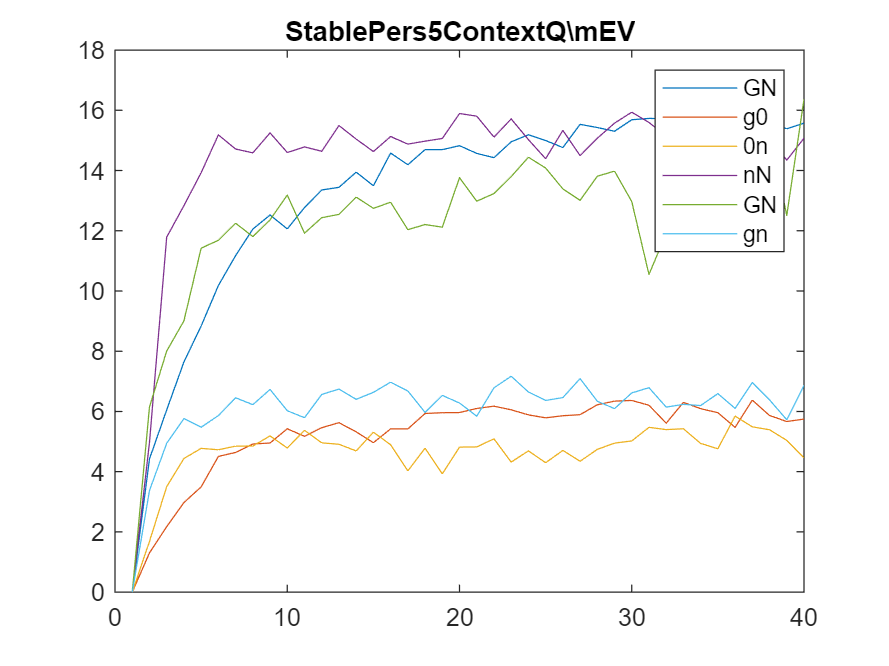

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


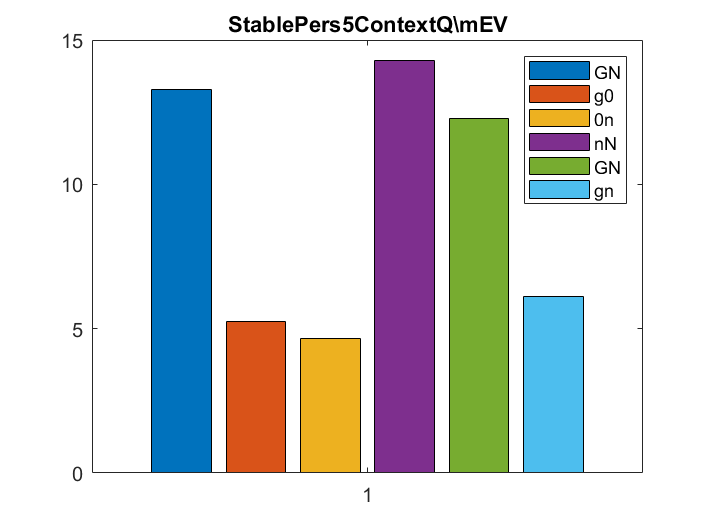

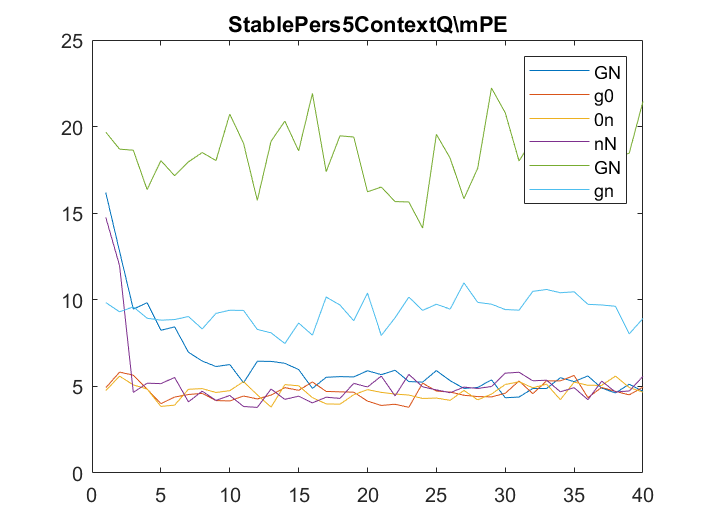

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


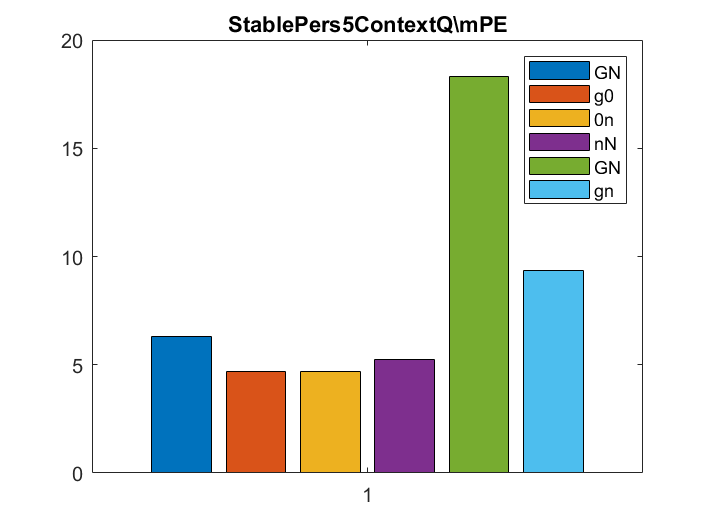

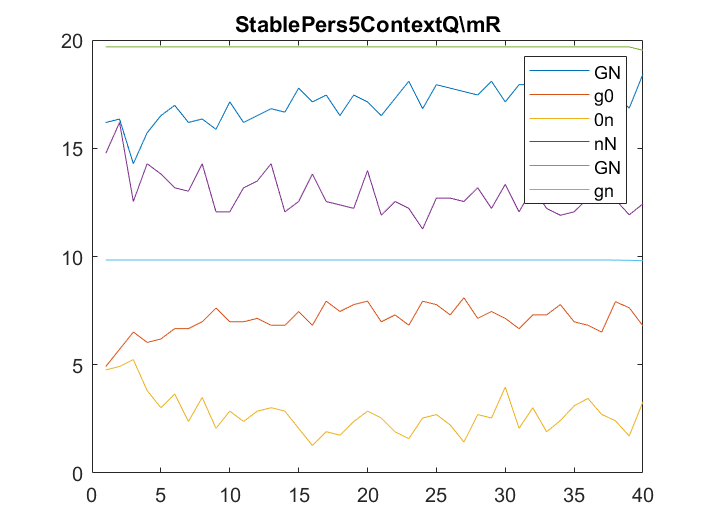

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


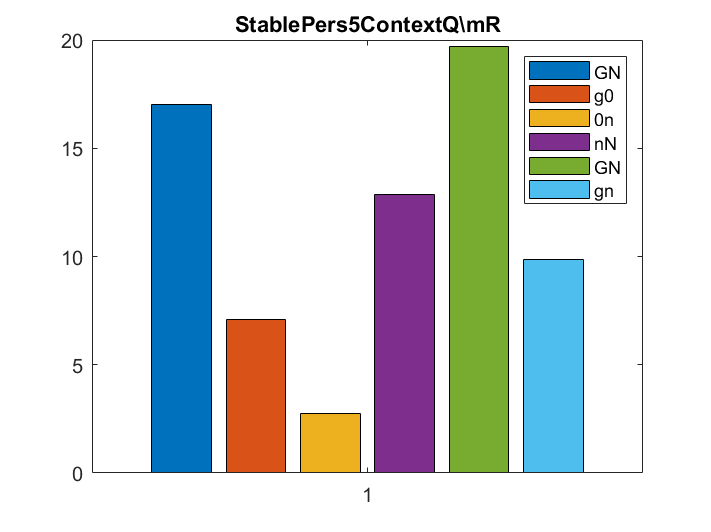

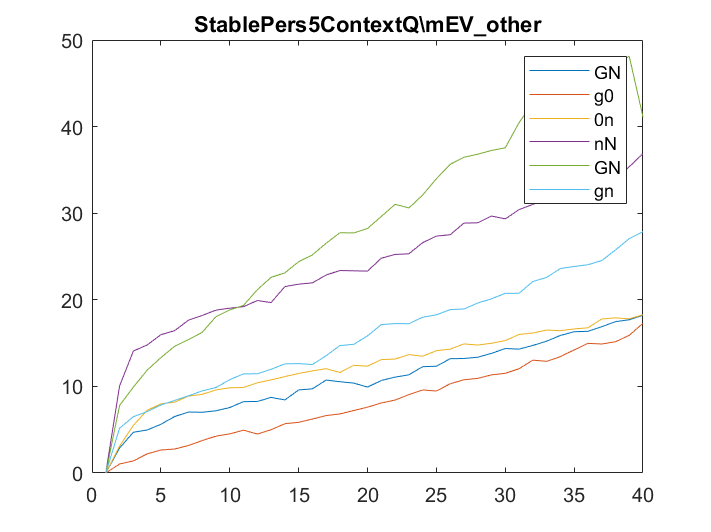

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


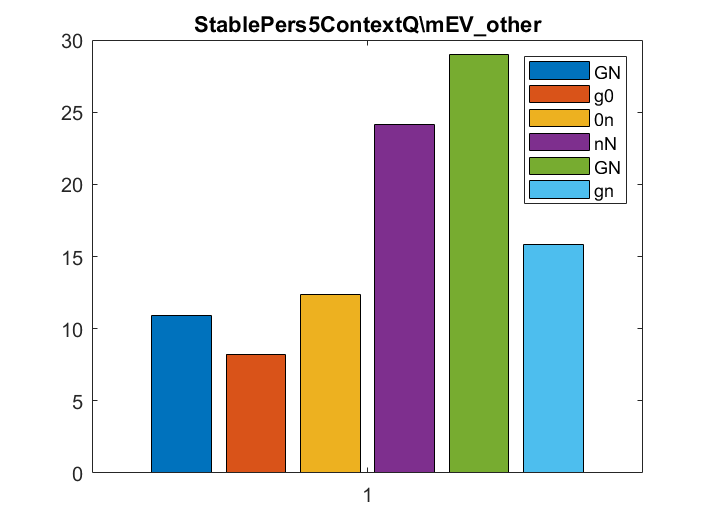

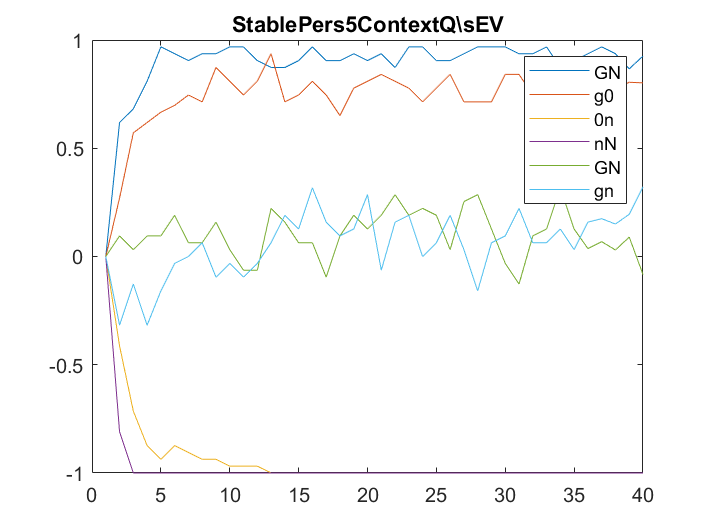

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


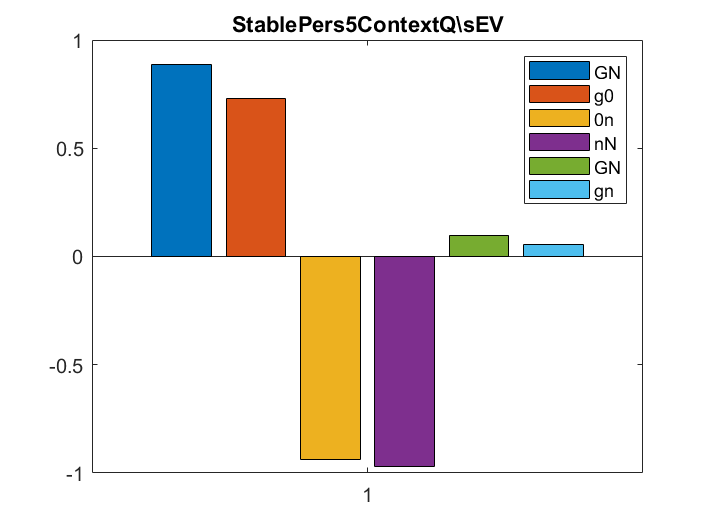

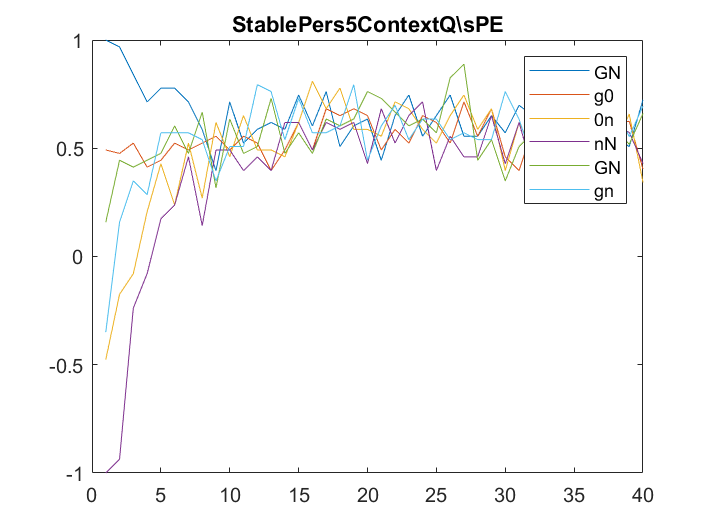

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


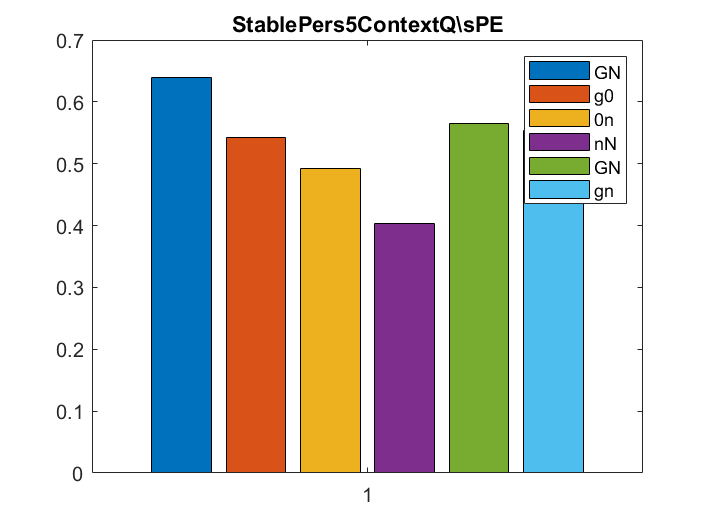

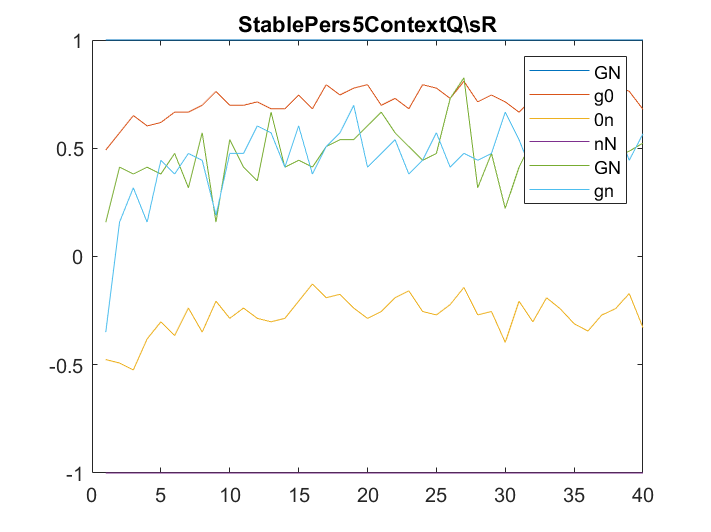

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


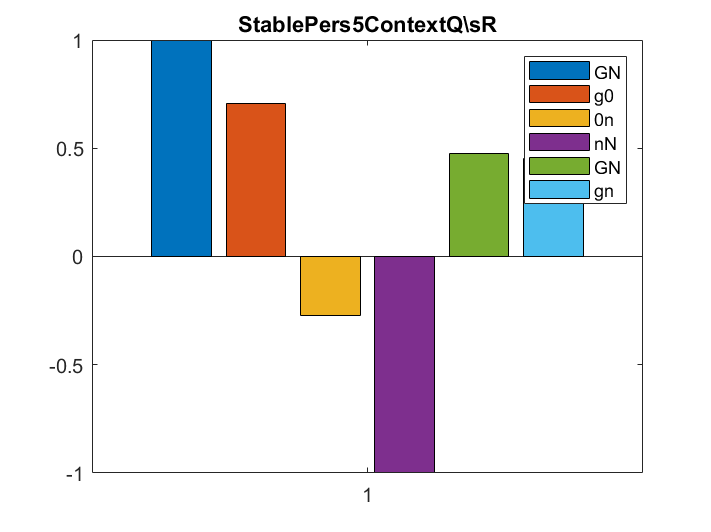

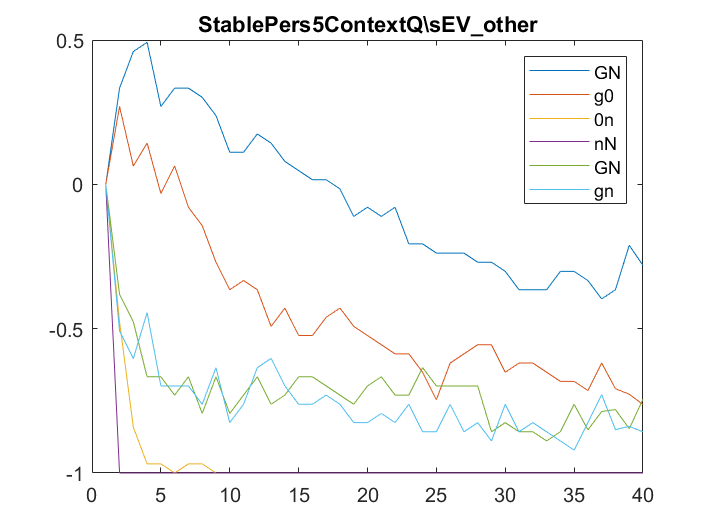

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


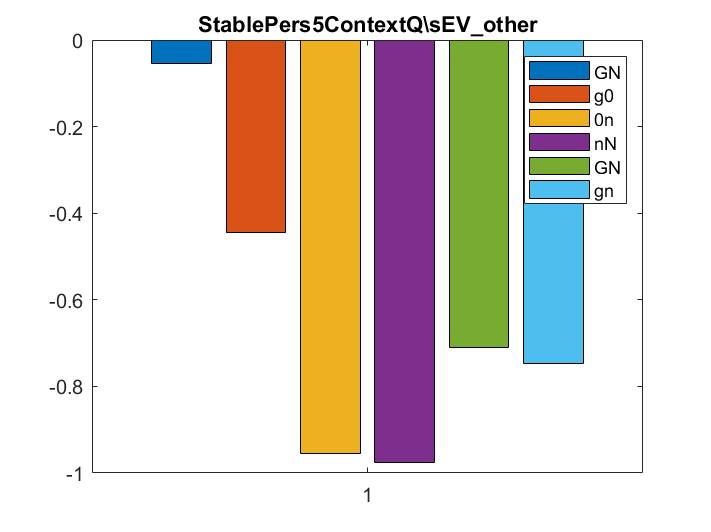


statenames = {'GN' 'g0' '0n' 'nN' 'GN' 'gn'};
for blk = 1:length(blkparam)

    dat = squeeze(nanmean(nanmean(blkparam{blk},2),3));

    figure;
    plot(dat')
    title(Deci.Analysis.Freq.Extra.Corr.Behavior{blk})
    legend(statenames)

    figure;
    dat = squeeze(nanmean(nanmean(nanmean(blkparam{blk},2),3),4));
    CleanBars(dat')
    title(Deci.Analysis.Freq.Extra.Corr.Behavior{blk})
    legend(statenames)
end


BehvTitlesInt = {'mEV:sEV' 'mPe:sPe' 'mR:sR', 'mEV_other:sEV_other'};

for blk = 1:4

    dat = squeeze(nanmean(nanmean(blkparam{blk},2),3)).*squeeze(nanmean(nanmean(blkparam{blk+4},2),3));
    figure;
    plot(dat')
    title(BehvTitlesInt{blk})
    legend(statenames)

    figure;
    dat = squeeze(nanmean(nanmean(nanmean(blkparam{blk},2),3),4)).*squeeze(nanmean(nanmean(nanmean(blkparam{blk+4},2),3),4));
    CleanBars(dat')
    title(BehvTitlesInt{blk})
    legend(statenames)

end
